# Profiles Data

% boge = xls2struct(BogData.xlsx');

% estrato = boge.ESTRATO;
% avg = boge.AVG;
% freq = boge.FREQ;
% decil = boge.DECIL;

% Consumos diarios promedio por estrato [kWh-dia], convertidos a consumo semanal
E1 = 4.35*7;
E2 = 4.73*7;
E3 = 5.01*7;
E4 = 5.26*7;
E5 = 6.51*7;
E6 = 8.88*7;
E = [E1, E2, E3, E4, E5, E6];


## Estimation for beta parameters for markov chain generation (skewed normal)

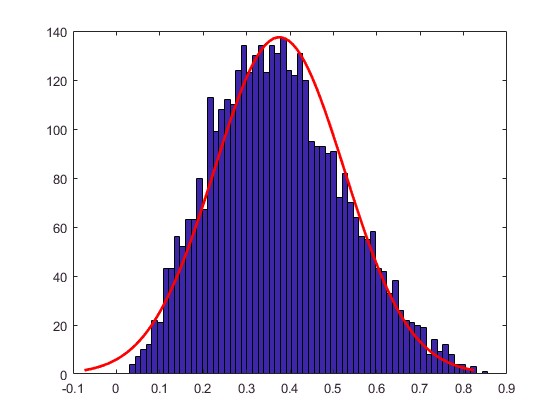

%probability density function verifying
r = betarnd(3.6,6,4000,1);
%r = rt/max(rt);
figure
histfit(r);

skewness(r)

ans = 0.2998

## Markov

% Cómo escogió los valores de lambda para cada aparato? Posiblemente
% teniendo en cuenta una cantidad de energía consumida promedio acumulada.
% cómo escogió la proporción de energía para cada aparato? con los
% criterios de apertura de puertas y eso y la duración de cada evento--?
% los sucesos no son cadenas de markov, porque el estado futuro depende en
% algunas ocasiones de la historia. e.gr. cuando se prende y sigue prendido
% cierto tiempo.

devices = xls2struct('devices.xlsx'); %cargar los aparatos que tienen las casas de cada usuario.
%load('Prefs.mat');
%number of populations (consumers, households)
P = 1;
% number of agents per population (devices)
N = length(devices.id);

%step_1_graph(P) % graph network generation, for the user's opinions interaction
%step_2_opdyn % opinion dynamics

%T_ = 14;%168/4;%10080/5; %weekly period with hourly resolution.
Tperf = 10080; % Perfiles generados con resolucion de 1 min.



## Selección perfil E4


 %PrefsOrig = zeros(N,Tperf,P);%randi([0 1], N,T_,P);
 valido=0;
 intento=0;
 while valido==0
     intento = intento + 1;
     Perfiles = Perfcas2(P,1);
     valido= (sum(Perfiles.Total)/(60*1000)- (5.26*7)) < 0.09;
 end

No genera gráfica
Fin perfil Nevera 3
No genera gráfica
Fin perfil Luminaria2OC
No genera gráfica
Fin perfil Luminaria2OC
No genera gráfica
Fin perfil Luminaria
No genera gráfica
Fin perfil Luminaria
No genera gráfica
Fin perfil Luminaria
No genera gráfica
Fin perfil Luminaria
No genera gráfica
Fin perfil Ducha
No genera gráfica
Fin perfil Lavadora
No genera gráfica
Fin perfil Lavadora
No genera gráfica
Fin perfil Lavadora
No genera gráfica
Fin perfil Lavadora
No genera gráfica
Fin perfil Plancha
No genera gráfica
Fin perfil Lavadora
No genera gráfica
Fin perfil Lavadora
No genera gráfica
Fin perfil Cargador Pc Portatil
No genera gráfica
Fin perfil Cargador Celular
No genera gráfica
Fin perfil Cargador Celular
No genera gráfica
Fin perfil Cargador Celular
No genera gráfica
Fin perfil Cargador Celular
No genera gráfica
Fin perfil Cargador Celular
No genera gráfica
Fin perfil Cargador Celular
No genera gráfica
Fin perfil Horno Microondas
No genera gráfica
Fin perfil Licuadora
No genera g

No genera gráfica
Fin perfil Nevera 3
No genera gráfica
Fin perfil Luminaria2OC
No genera gráfica
Fin perfil Luminaria2OC
No genera gráfica
Fin perfil Luminaria
No genera gráfica
Fin perfil Luminaria
No genera gráfica
Fin perfil Luminaria
No genera gráfica
Fin perfil Luminaria
No genera gráfica
Fin perfil Ducha
No genera gráfica
Fin perfil Lavadora
No genera gráfica
Fin perfil Lavadora
No genera gráfica
Fin perfil Lavadora
No genera gráfica
Fin perfil Lavadora
No genera gráfica
Fin perfil Plancha
No genera gráfica
Fin perfil Lavadora
No genera gráfica
Fin perfil Lavadora
No genera gráfica
Fin perfil Cargador Pc Portatil
No genera gráfica
Fin perfil Cargador Celular
No genera gráfica
Fin perfil Cargador Celular
No genera gráfica
Fin perfil Cargador Celular
No genera gráfica
Fin perfil Cargador Celular
No genera gráfica
Fin perfil Cargador Celular
No genera gráfica
Fin perfil Cargador Celular
No genera gráfica
Fin perfil Horno Microondas
No genera gráfica
Fin perfil Licuadora
No genera g

 intento

intento = 2

 sum(Perfiles.Total)/(60*1000)

ans = 36.5852

## hmm gen x1

for id = {'A','B','C','D1','D2','E','F','G','H','J','K','L','M','N','O'}
    unique(Perfiles.(id{1}))
end 

ans =      0
   120


ans =      0
    10
    25
    35
    50
    60
    70
    75
    85
    95


ans =            0
        3500


ans =      0
    70


ans =      0
    70


ans =     16
    88
   160


ans = 0

ans =      0
   400


ans =      0
    21
   140


ans =      0
    12
    60


ans =          0
    1.7500
    2.1000
    2.4500
    2.8000
    3.1500
    3.5000
    7.0000
    7.7000
    8.4000


ans =            0
        1250


ans =      0
   400


ans =     18
    20


ans =      0
    50


 
 
 devPow  = sum(Perfiles.Total)/(60*1000) %consumo semanal E4 referencia

devPow = 36.5852

  seqNevera = Perfiles.A;
  stNevera = logical(seqNevera)+1;
 
[TRANS_NEVERA, EMIS_NEVERA] = hmmestimate(stNevera', stNevera') 

TRANS_NEVERA =     0.9844    0.0156
    0.0330    0.9670


EMIS_NEVERA =      1     0
     0     1



TRANS_NEVERA = [0.9844 0.0156;0.0433 0.9567]

TRANS_NEVERA =     0.9844    0.0156
    0.0433    0.9567



testNevPow = zeros(1,1000);
for i = 1:2000
[test_seq,test_states] = hmmgenerate(Tperf,TRANS_NEVERA,EMIS_NEVERA);
%[test_seq,test_states] = hmmgenerate(Tperf,devices.TRANS.A,devices.EMIS);
test_nevera_normalizado = (test_seq - 1);
testNevPow(i) = devices.power(1)*sum(test_nevera_normalizado)/(60*1000);
end
mean(testNevPow)

ans = 5.3145

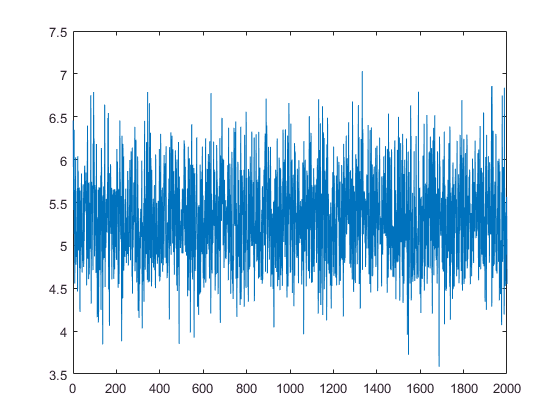

plot(testNevPow)

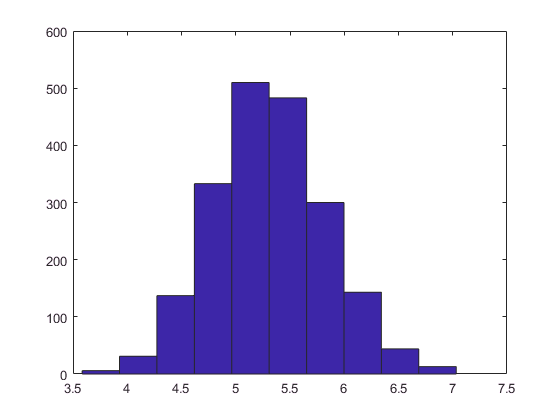

hist(testNevPow)


%EMIS = [1 0; 0 1]
%TRANS_NEVERA_E4 = [0.9846 0.0154; 0.0333 0.9667] % from hmmestimate y un caso aleatorio
%TNevera_E3 = [0.99 0.01; 0.0333 0.9667]

%valores promedio para cada electrodoméstico en el caso de referencia E4

    Nevera = 6.42;
    Iluminacion = 6.6658;
    Ducha = 6.5917;
    TV = 6.6822;
    CodificadorTV = 7.7076;
    Plancha = 0.4767;
    Lavadora = 0.3643;
    PC = 1.9077;
    Laptop = 1.1853;
    CargadoresCelular = 0.6712;
    Microondas = 2.2173;
    Licuadora = 0.0533;
    Router = 3.2504;
    EquipoSonido = 6.2039;

## Ajuste matrices para cada aparato y por cada estrato.

% devices mean reference (E4) weekly consumption in kWh.
%devices.E4 = [6.42 6.6658 6.5917 6.6822 7.7076 0.4767 0.3643 1.9077 1.1853 0.6712 2.2173 0.0533 3.2504 6.2039]' %

for id = {'A','B','C','D1','D2','E','F','G','H','J','K','L','M','N','O'}
    devices.E4prom.(id{1}) = sum(Perfiles.(id{1}))/(60*1000); %consumo semanal E4 referencia
    devices.E4percent.(id{1}) = 100*devices.E4prom.(id{1})/(sum(Perfiles.Total)/(60*1000));
end

%se asume que el consumo para cada dispositivo de diferente estrato mantiene la proporción,
%excepto para PC, laptop y cargador de celular, que se asumen constantes entre estratos.
%i=1;
for id = {'A','C','D1','D2','F','G','L','M','N','O'}
    seqDev = Perfiles.(id{1});
    stateDev = logical(seqDev)+1;
    [devices.TRANS.(id{1}), devices.EMIS] =  hmmestimate(stateDev', stateDev'); %consumo semanal E4 referencia
    %i = i+1;
end

%i=1;
step = 0.01;
%for id = {'A','B','C','D','E','F','G','H','J','K','L','M','N','O'}
for id = {'A','D1'}
    percent = devices.E4percent.(id{1});
    for estrato = 1:3
       goalPow = E(estrato)*percent*0.01; % potencia promedio que deberia tener la cadena generada
       est = strcat('E',num2str(estrato))
       devices.(est).TRANS.(id{1}) = matrixAdjust(estrato, goalPow, (id{1}), devices.TRANS.(id{1}), max(Perfiles.(id{1})), step, Tperf)
    end
   % i = i+1;
end

est = 'E1'

    0.9844    0.0156
    0.0330    0.9670



devices = struct with fields:
                  id: {14×1 cell}
                name: {14×1 cell}
               power: [14×1 double]
        weekly_use_h: [14×1 double]
    time_per_use_min: [14×1 double]
              E4prom: [1×1 struct]
           E4percent: [1×1 struct]
               TRANS: [1×1 struct]
                EMIS: [2×2 double]
                  E1: [1×1 struct]


est = 'E2'

    0.9844    0.0156
    0.0330    0.9670



devices = struct with fields:
                  id: {14×1 cell}
                name: {14×1 cell}
               power: [14×1 double]
        weekly_use_h: [14×1 double]
    time_per_use_min: [14×1 double]
              E4prom: [1×1 struct]
           E4percent: [1×1 struct]
               TRANS: [1×1 struct]
                EMIS: [2×2 double]
                  E1: [1×1 struct]
                  E2: [1×1 struct]


est = 'E3'

    0.9844    0.0156
    0.0330    0.9670



devices = struct with fields:
                  id: {14×1 cell}
                name: {14×1 cell}
               power: [14×1 double]
        weekly_use_h: [14×1 double]
    time_per_use_min: [14×1 double]
              E4prom: [1×1 struct]
           E4percent: [1×1 struct]
               TRANS: [1×1 struct]
                EMIS: [2×2 double]
                  E1: [1×1 struct]
                  E2: [1×1 struct]
                  E3: [1×1 struct]


est = 'E1'

    0.9967    0.0033
    1.0000         0



devices = struct with fields:
                  id: {14×1 cell}
                name: {14×1 cell}
               power: [14×1 double]
        weekly_use_h: [14×1 double]
    time_per_use_min: [14×1 double]
              E4prom: [1×1 struct]
           E4percent: [1×1 struct]
               TRANS: [1×1 struct]
                EMIS: [2×2 double]
                  E1: [1×1 struct]
                  E2: [1×1 struct]
                  E3: [1×1 struct]


est = 'E2'

    0.9967    0.0033
    1.0000         0



devices = struct with fields:
                  id: {14×1 cell}
                name: {14×1 cell}
               power: [14×1 double]
        weekly_use_h: [14×1 double]
    time_per_use_min: [14×1 double]
              E4prom: [1×1 struct]
           E4percent: [1×1 struct]
               TRANS: [1×1 struct]
                EMIS: [2×2 double]
                  E1: [1×1 struct]
                  E2: [1×1 struct]
                  E3: [1×1 struct]


est = 'E3'

    0.9967    0.0033
    1.0000         0



devices = struct with fields:
                  id: {14×1 cell}
                name: {14×1 cell}
               power: [14×1 double]
        weekly_use_h: [14×1 double]
    time_per_use_min: [14×1 double]
              E4prom: [1×1 struct]
           E4percent: [1×1 struct]
               TRANS: [1×1 struct]
                EMIS: [2×2 double]
                  E1: [1×1 struct]
                  E2: [1×1 struct]
                  E3: [1×1 struct]
